Processing /Users/macos/Documents/MATLAB/Simulation_capstone/dataset/at home/700hz/700hz behind.WAV...


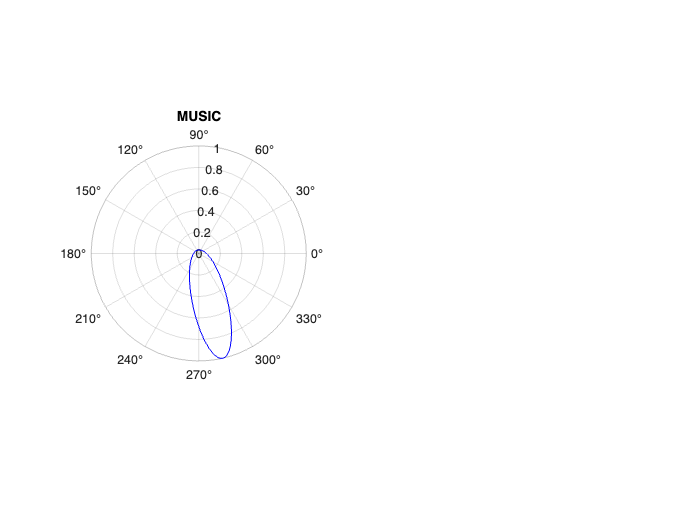

700hz behind.WAV - Results:


MUSIC: Max angle = 283.00°, value = 1.00


Processing /Users/macos/Documents/MATLAB/Simulation_capstone/dataset/at home/700hz/700hz left.WAV...


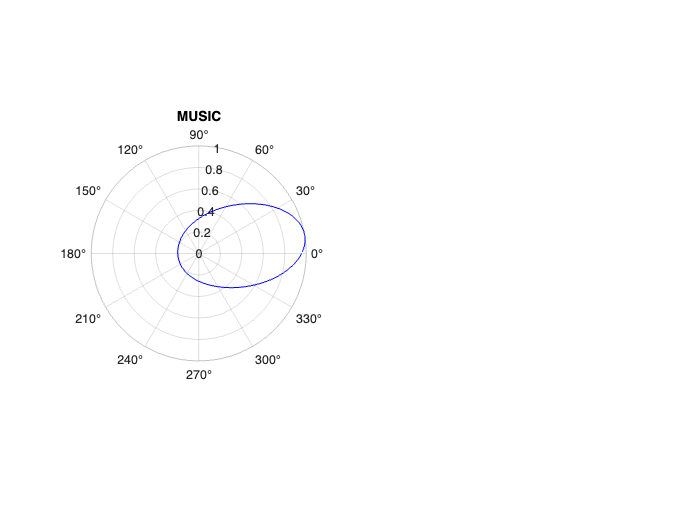

700hz left.WAV - Results:


MUSIC: Max angle = 10.00°, value = 1.00


Processing /Users/macos/Documents/MATLAB/Simulation_capstone/dataset/at home/700hz/700hz right.WAV...


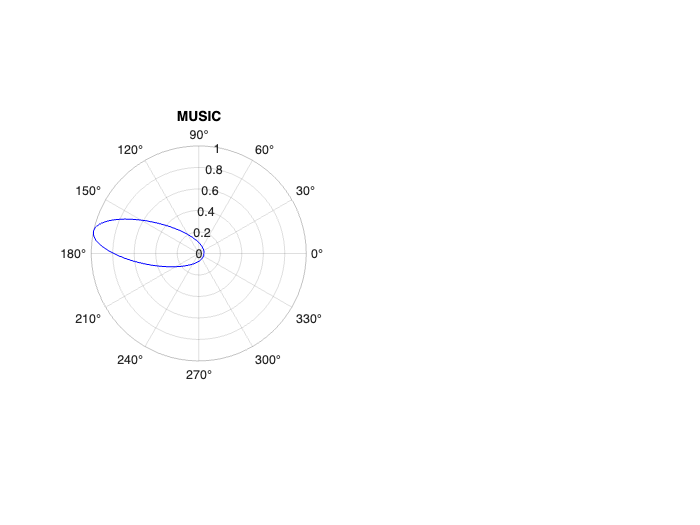

700hz right.WAV - Results:


MUSIC: Max angle = 168.00°, value = 1.00


Processing /Users/macos/Documents/MATLAB/Simulation_capstone/dataset/at home/700hz/700hzfront.WAV...


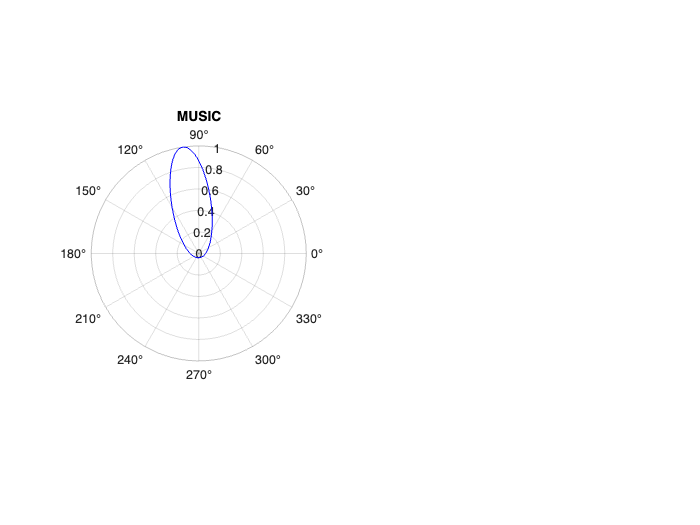

700hzfront.WAV - Results:


MUSIC: Max angle = 99.00°, value = 1.00



fs = 32000;            
c = 343;                
d = 0.06;               
mic_positions = [0, 0; d, 0; d, d; 0, d]; 
angles = 0:1:359;       
N = 4096;               
f0 = 700;               
bandwidth = 100;       


vad_energy_thresh = 1e-6;
vad_zcr_thresh = 0.03;

base_folder = '/Users/macos/Documents/MATLAB/Simulation_capstone/dataset/at home/700hz';
file_pattern = fullfile(base_folder, '**/*.wav');  % Search recursively for WAV files
wav_files = dir(file_pattern);

if isempty(wav_files)
    error('No WAV files found in the specified directory.');
end

for i = 1:length(wav_files)
    audio_file = fullfile(wav_files(i).folder, wav_files(i).name);
    fprintf('Processing %s...\n', audio_file);
    [audio, fs] = audioread(audio_file);
    
    if size(audio, 2) ~= 4
        error('Expected 4-channel WAV file.');
    end
    
    frame = audio(1:N, :);
    
    powers_no_vad = music_beamforming(frame, fs, mic_positions, angles, c, N, f0, bandwidth);
    
    if vad_detection(frame(:, 1), vad_energy_thresh, vad_zcr_thresh)
        powers_vad = music_beamforming(frame, fs, mic_positions, angles, c, N, f0, bandwidth);
    else
        powers_vad = zeros(size(angles)); % If VAD inactive, zero power
    end
    
    figure;
    subplot(1, 2, 1);
    polarplot(deg2rad(mod(360 - angles, 360)), powers_no_vad, 'b');
    title('MUSIC');
   
    
    [max_val_nv, idx_nv] = max(powers_no_vad);
    max_angle_nv = mod(360 - angles(idx_nv), 360);
    

    
    fprintf('\n%s - Results:\n', wav_files(i).name);
    fprintf('MUSIC: Max angle = %.2f°, value = %.2f\n', max_angle_nv, max_val_nv);
    

end

function powers = music_beamforming(frame, fs, mic_positions, angles, c, N, f0, bandwidth)
% music_beamforming - Perform MUSIC algorithm for DoA estimation
%
% INPUTS:
%   frame        - Audio frame (Nx4) for 4 microphones
%   fs           - Sampling rate (Hz)
%   mic_positions - 4x2 matrix of microphone positions [x, y]
%   angles       - Array of beamforming angles (degrees)
%   c            - Speed of sound (m/s)
%   N            - FFT length
%   f0           - Target frequency (Hz)
%   bandwidth    - Frequency range (± around f0)
%
% OUTPUT:
%   powers       - MUSIC spectrum (normalized)

frame = frame .* hann(N);        % Apply Hann window
X = fft(frame, N);               % FFT [N x 4]
f_axis = (0:N-1) * fs / N;       % Frequency axis

bins = round((f0 - bandwidth/2)/fs * N) : round((f0 + bandwidth/2)/fs * N);

R = zeros(4, 4);
for b = bins
    if b > N  
        continue;
    end
    Xf = X(b, :).';             
    R = R + (Xf * Xf');         
end
R = R / length(bins);           

[Evecs, Evals] = eig(R);
[~, idx] = sort(diag(Evals), 'descend');
Evecs = Evecs(:, idx);
En = Evecs(:, 2:end);         

powers = zeros(size(angles));
f_center = f0;

for i = 1:length(angles)
    theta = deg2rad(angles(i));
    direction = [cos(theta), sin(theta)];
    delays = mic_positions * direction' / c;
    steering = exp(-1j * 2 * pi * f_center * delays);  % [4 x 1]
    

    powers(i) = 1 / real(steering' * (En * En') * steering);
end

powers = powers / max(powers);
end

function is_active = vad_detection(frame, vad_energy_thresh, vad_zcr_thresh)
% vad_detection - Perform VAD (Voice Activity Detection) on a frame
%
% INPUTS:
%   frame            - Audio frame (Nx1) from one microphone
%   vad_energy_thresh - Energy threshold for VAD
%   vad_zcr_thresh   - Zero-crossing rate (ZCR) threshold for VAD
%
% OUTPUT:
%   is_active        - Boolean indicating if VAD is active (1 = active, 0 = silent)

% Calculate energy and ZCR
N = length(frame);
energy = sum(frame.^2) / N;
zcr = sum(abs(diff(sign(frame)))) / (2 * N);

% Determine if the frame is active
is_active = (energy >= vad_energy_thresh) && (zcr >= vad_zcr_thresh);
end
